clc; clear; close all;

rng(0);

n = 256;
m = 120;
s = 10;

A = randn(m,n);
A = A ./ vecnorm(A);

x_true = zeros(n,1);
idx = randperm(n,s);
x_true(idx) = randn(s,1);

b = A * x_true;

params.rho     = 1;
params.lambda  = 0.005;          % WORKING VALUE
params.v       = norm(A)^2;      % IMPORTANT
params.maxIter = 300;
params.tol     = 1e-6;
params.s       = s;

[x_rec, err, obj] = ILSTAT_ADMM(A, b, x_true, params);

fprintf('Recovered sparsity = %d\n', nnz(x_rec));

Recovered sparsity = 10


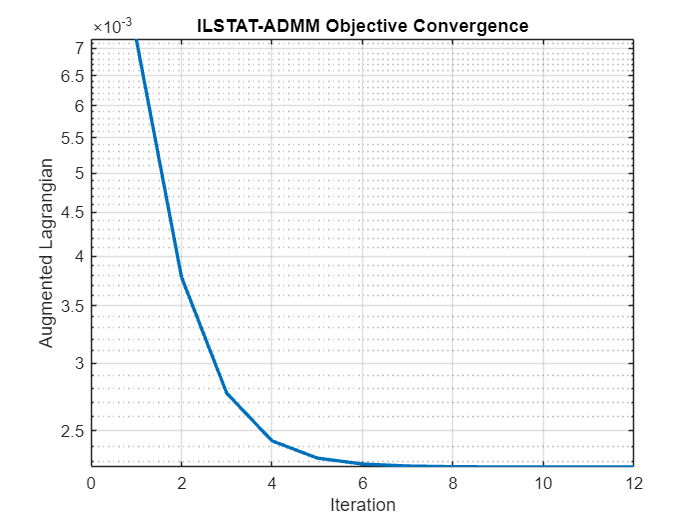


figure;
semilogy(obj,'LineWidth',2);
grid on;
xlabel('Iteration');
ylabel('Augmented Lagrangian');
title('ILSTAT-ADMM Objective Convergence');

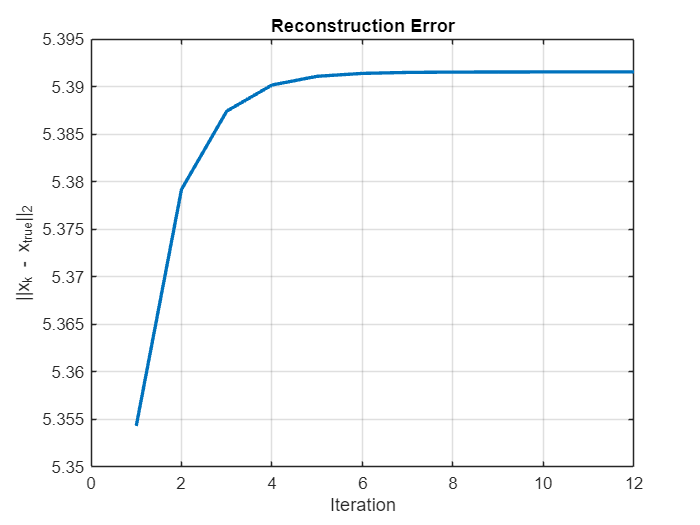


figure;
plot(err,'LineWidth',2);
grid on;
xlabel('Iteration');
ylabel('||x_k - x_{true}||_2');
title('Reconstruction Error');

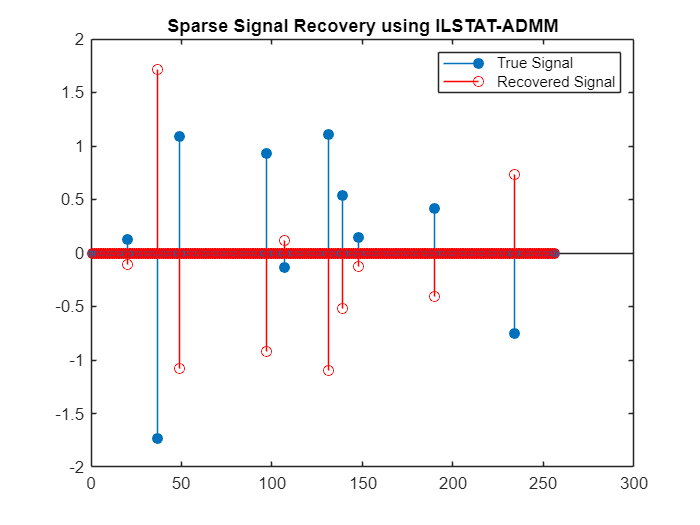


figure;
stem(x_true,'filled'); hold on;
stem(x_rec,'r');
legend('True Signal','Recovered Signal');
title('Sparse Signal Recovery using ILSTAT-ADMM');